clc; clear; close all;
% Import functions path
addpath(genpath(strcat(pwd, '\Functions')))
addpath(genpath(strcat(pwd, '\Functions\Globals')))

setPreamble("Default"); setTransform("FFT"); setCoding("REP");
% Parameters
filename='Test/test_file.txt';
fileID = fopen(filename,'r');
data = fread(fileID, '*ubit1', 'ieee-le');
L = 1000;
R = 6;
codeRate = 1/2;
modulation_type = 'BPSK';
rep_type = 'Float';

% Transmitter
snr = 11;
% setPreamble("double");
transmitted_frames = Wifi_Transmitter(data, L, R, codeRate, modulation_type, rep_type);
% Channel
rxed_frames = apply_channel(transmitted_frames, snr);
% Receiver
equalization_method = 'Weiner';
[decoded_data, ~, ~] = Wifi_Receiver(rxed_frames, equalization_method, rep_type, snr);
output_fileID = fopen('Output/output_test1_BPSK_6_5.txt','w');
fwrite(output_fileID, decoded_data,'*ubit1', 'ieee-le');

## Investigating the effect of Preamble Length

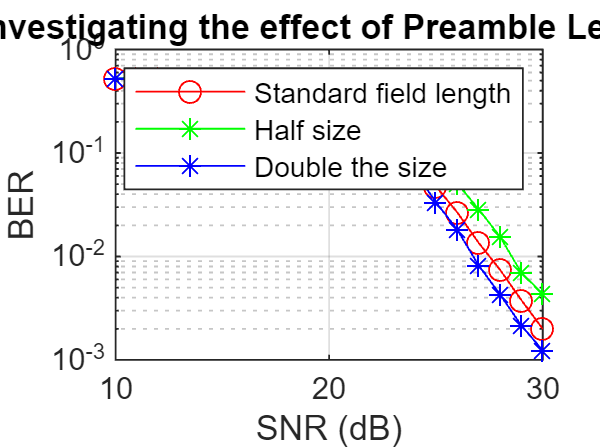

SNR_DB_Arr = 10:30;
L = 1000;
R = 54;
codeRate = 3/4;
modulation_type = '64QAM';
rep_type = 'Float';
equalization_method = 'Weiner';

setPreamble("");
BER_Vals_default_preamble = [];
for snr = SNR_DB_Arr
    % Transmitter
    transmitted_frames = Wifi_Transmitter(data, L, R, codeRate, modulation_type, rep_type);
    % Channel
    rxed_frames = apply_channel(transmitted_frames, snr);
    % Receiver
    equalization_method = 'Weiner';
    [decoded_data, ~, ~] = Wifi_Receiver(rxed_frames, equalization_method, rep_type, snr);
    [BER, ratio] = biterr(decoded_data',data);
    BER_Vals_default_preamble = [BER_Vals_default_preamble ratio];
end
setPreamble("half");
BER_Vals_half_preamble = [];
for snr = SNR_DB_Arr
    % Transmitter
    transmitted_frames = Wifi_Transmitter(data, L, R, codeRate, modulation_type, rep_type);
    % Channel
    rxed_frames = apply_channel(transmitted_frames, snr);
    % Receiver
    equalization_method = 'Weiner';
    [decoded_data, ~, ~] = Wifi_Receiver(rxed_frames, equalization_method, rep_type, snr);
    [BER, ratio] = biterr(decoded_data',data);
    BER_Vals_half_preamble = [BER_Vals_half_preamble ratio];
end
setPreamble("double");
BER_Vals_double_preamble = [];
for snr = SNR_DB_Arr
    % Transmitter
    transmitted_frames = Wifi_Transmitter(data, L, R, codeRate, modulation_type, rep_type);
    % Channel
    rxed_frames = apply_channel(transmitted_frames, snr);
    % Receiver
    equalization_method = 'Weiner';
    [decoded_data, ~, ~] = Wifi_Receiver(rxed_frames, equalization_method, rep_type, snr);
    [BER, ratio] = biterr(decoded_data',data);
    BER_Vals_double_preamble = [BER_Vals_double_preamble ratio];
end
figure();
semilogy(SNR_DB_Arr, BER_Vals_default_preamble,'r-o', ...
    SNR_DB_Arr, BER_Vals_half_preamble,'g-*', ...
    SNR_DB_Arr, BER_Vals_double_preamble, 'b-*');
title('Investigating the effect of Preamble Length');
xlabel('SNR (dB)'); ylabel('BER');
grid on;
legend('Standard field length', 'Half size', 'Double the size');

## Investigating the effect of the transform techniques

L = 1000;R = 6;codeRate = 1/2;modulation_type = 'BPSK';rep_type = 'Float';equalization_method = 'Weiner';
setPreamble("Default");
setTransform("FFT");
% ====== FFT ========
disp("For FFT:-")

For FFT:-


tic
% Transmitter
transmitted_frames = Wifi_Transmitter(data, L, R, codeRate, modulation_type, rep_type);
% Channel
rxed_frames = apply_channel(transmitted_frames, 30);
% Receiver
[decoded_data, ~, ~] = Wifi_Receiver(rxed_frames, equalization_method, rep_type, 0);
toc

Elapsed time is 4.180248 seconds.


output_fileID = fopen('Output/test2_fft.txt','w');
fwrite(output_fileID, decoded_data,'*ubit1', 'ieee-le');
% ====== DCT ========
setTransform("DCT");
disp("For DCT:-")

For DCT:-


tic
% Transmitter
transmitted_frames = Wifi_Transmitter(data, L, R, codeRate, modulation_type, rep_type);
% Channel
rxed_frames = apply_channel(transmitted_frames, 30);
% Receiver
[decoded_data, ~, ~] = Wifi_Receiver(rxed_frames, equalization_method, rep_type, 0);
toc

Elapsed time is 21.282111 seconds.


output_fileID = fopen('Output/test2_dct.txt','w');
fwrite(output_fileID, decoded_data,'*ubit1', 'ieee-le');

## Investigating the effect of the equalization

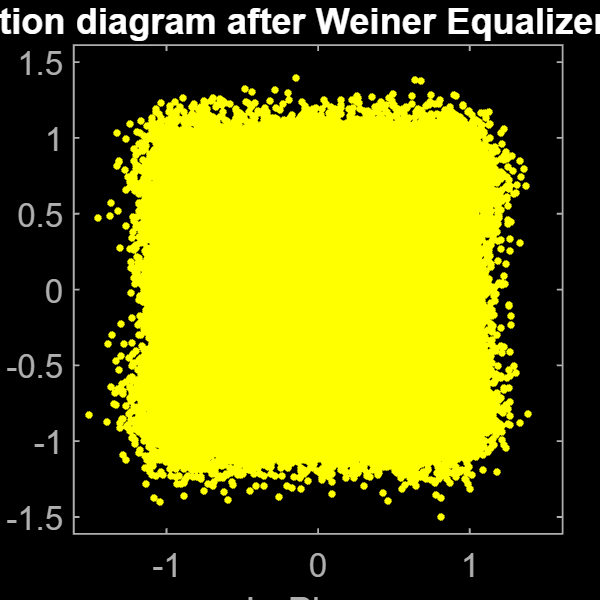

setPreamble("");setTransform("FFT");
SNR_DB_Arr = 10:11;
L = 1000;
R = 54;
codeRate = 3/4;
modulation_type = '64QAM';
rep_type = 'Float';

snr = 10;
% Transmitter
transmitted_frames = Wifi_Transmitter(data, L, R, codeRate, modulation_type, rep_type);
% Channel
rxed_frames = apply_channel(transmitted_frames, snr);
% Receiver
[~, ~, eq_frames_w] = Wifi_Receiver(rxed_frames, "Weiner", rep_type, snr);
[~, ~, eq_frames_zf] = Wifi_Receiver(rxed_frames, "ZF", rep_type, snr);

scatterplot(eq_frames_w);
title('Constellation diagram after Weiner Equalizer (SNR = 10)');

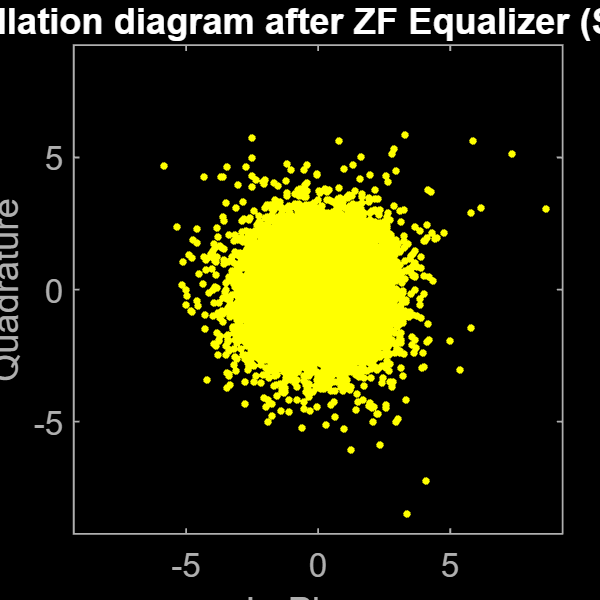

scatterplot(eq_frames_zf);
title('Constellation diagram after ZF Equalizer (SNR = 10)');

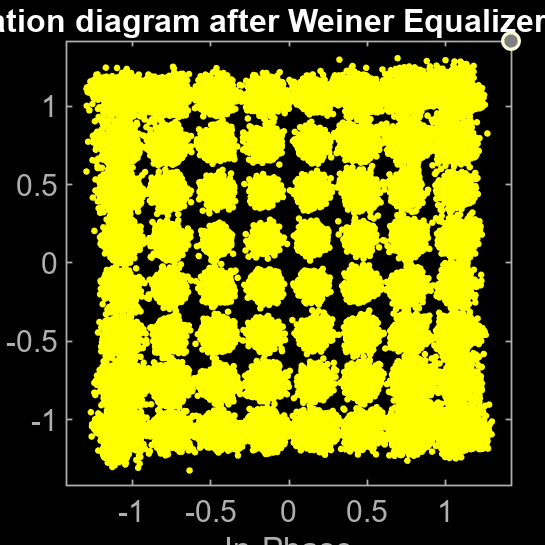


snr = 30;
% Transmitter
transmitted_frames = Wifi_Transmitter(data, L, R, codeRate, modulation_type, rep_type);
% Channel
rxed_frames = apply_channel(transmitted_frames, snr);
% Receiver
[~, ~, eq_frames_w] = Wifi_Receiver(rxed_frames, "Weiner", rep_type, snr);
[~, ~, eq_frames_zf] = Wifi_Receiver(rxed_frames, "ZF", rep_type, snr);

scatterplot(eq_frames_w);
title('Constellation diagram after Weiner Equalizer (SNR = 30)');

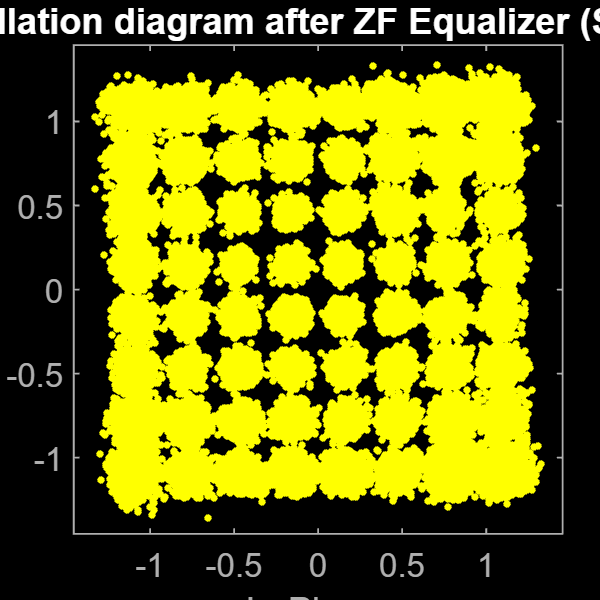

scatterplot(eq_frames_zf);
title('Constellation diagram after ZF Equalizer (SNR = 30)');

## Investigating the effect of channel coding technique

SNR_DB_Arr = 11:30;
L = 1000;
R = 6;
codeRate = 1/2;
modulation_type = 'BPSK';
rep_type = 'Float';
equalization_method = 'Weiner';

setPreamble("");setTransform("FFT");
setCoding("REP");
BER_Vals_repition = [];
for snr = SNR_DB_Arr
    % Transmitter
    transmitted_frames = Wifi_Transmitter(data, L, R, codeRate, modulation_type, rep_type);
    % Channel
    rxed_frames = apply_channel(transmitted_frames, snr);
    % Receiver
    [decoded_data, ~, ~] = Wifi_Receiver(rxed_frames, equalization_method, rep_type, snr);
    [BER, ratio] = biterr(decoded_data',data);
    BER_Vals_repition = [BER_Vals_repition ratio];
end
setCoding("CONV");
BER_Vals_conv = [];
for snr = SNR_DB_Arr
    % Transmitter
    transmitted_frames = Wifi_Transmitter(data, L, R, codeRate, modulation_type, rep_type);
    % Channel
    rxed_frames = apply_channel(transmitted_frames, snr);
    % Receiver
    [decoded_data, ~, ~] = Wifi_Receiver(rxed_frames, equalization_method, rep_type, snr);
    [BER, ratio] = biterr(decoded_data',data);
    BER_Vals_conv = [BER_Vals_conv ratio];
end

Index exceeds the number of array elements. Index must not exceed 8000.

Error in conv_decode (line 44)
    outputStream = outputStream(1:L); % to cancel the zero-padding effect that happend in the encoder

Error in Wifi_Receiver (line 10

% setCoding("LDPC");
% BER_Vals_LDPC = [];
% for snr = SNR_DB_Arr
%     % Transmitter
%     transmitted_frames = Wifi_Transmitter(data, L, R, codeRate, modulation_type, rep_type);
%     % Channel
%     rxed_frames = apply_channel(transmitted_frames, snr);
%     % Receiver
%     equalization_method = 'Weiner';
%     [decoded_data, ~, ~] = Wifi_Receiver(rxed_frames, equalization_method, rep_type, snr);
%     [BER, ratio] = biterr(decoded_data',data);
%     BER_Vals_LDPC = [BER_Vals_LDPC ratio];
% end
figure();
semilogy(SNR_DB_Arr, BER_Vals_conv,'r-o', ...
    SNR_DB_Arr, BER_Vals_repition,'g-*');
title('Investigating the effect of channel coding technique');
xlabel('SNR (dB)'); ylabel('BER');
grid on;
legend('Conv Coding 1/2', 'Repitition Coding 1/3');